# MATH2089 Lab 3

In this week's lab, we will go about computing probabilities of various distributions. 

## Question 1

Let $X\sim\text{Ber}(p)}$, so that $\mathbb{P}\{X = 1\} = p = 1 -  \mathbb{P}\{X = 0\}$. We can think of $X$ has measuring the outcome of a coin toss, where *Heads*$\equiv$1 and *Tails*$\equiv$0 and the probability of tossing Heads is $p$. Let $X_{1},\dots,X_{n}$ be an independent sequence of $\text{Ber}(p)$ random variables and let $Y = \sum^{n}_{i = 1}X_{i}$. Then $Y\sim\text{Bin}(n,p)$. Here, we analogously think of $Y$as the number of Heads we observe from a sequence of $n$ coin tosses where the probability of heads is again $p$. Clearly $Y\in\{0,\dots,n\}$ and has corresponding density $f(y) = \binom{n}{y}p^{y}(1 - p)^{n - y}$. 

We can evaluate the probabilities using the `bino_()` family of functions. 

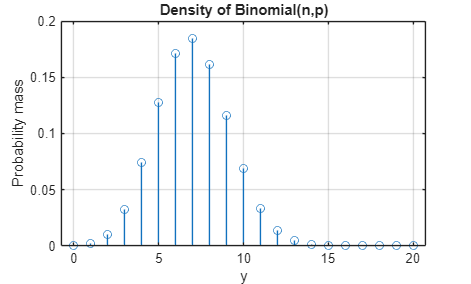

% Set parameters for the binomial distribution
n =20;
p = 0.35;

y = 0:n;
binomial_density = binopdf(y, n, p);
binomial_distribution = binocdf(y, n, p);

% Plot the Binomial density function
stem(y, binomial_density);
title('Density of Binomial(n,p)');
xlabel('y');
ylabel('Probability mass');
grid on;

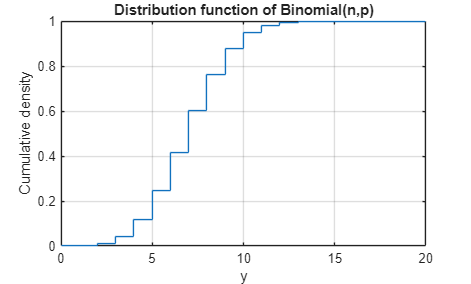


% Plot the Binomial distribution function
stairs(y, binomial_distribution);
title('Distribution function of Binomial(n,p)');
xlabel('y');
ylabel('Cumulative density');
grid on;

To answer the questions, keep note of the fact that, for any nonempty $A\subseteq\{0,\dots,n\}$ and integer $k$, $\mathbb{P}\{Y\in A\} = \sum_{y\in A}f(y)$ and

$\mathbb{P}\{Y < k\} = \mathbb{P}\{Y\leq k - 1\} = F(k - 1)$,

where $F$ is the distribution function. For our questions, set $n = 20$ and $p = 0.35$.

binopdf(5, n, p)

ans = 0.1272

binocdf(14, n, p) - binocdf(4, n, p) % also sum(binopdf(5:14, n, p))

ans = 0.8815

binocdf(15, n, p) - binocdf(5, n, p) % also sum(binopdf(6:15, n, p))

ans = 0.7546

sum(binopdf([1,5,9,17], n, p))

ans = 0.2450

1 - sum(binopdf([5, 13, 16], n, p))

ans = 0.8683

To answer part (b), consider the success of each test question as a Bernoulli distribution, where the probability of getting a particular question correct is $1/5$—or more generally $1/m$, where $m$ is the number of options available per question. Let $Y$ be the number of questions the student guesses correctly. Then $Y\sim\text{Bin}(n,p)$, where $n$ is the number of questions and $p$ is the probability of correctly guessing any particular question correct. The probability that *all the questions are guessed correctly* is $\mathbb{P}\{Y = n\} = f(n) = p^{n}$. The probability that the student passes any given test with $n$ questions— scores at least $n / 2$—is given by  


$$\mathbb{P}\left\{Y \geq \frac{n}{2}\right\} = 1 - \mathbb{P}\left\{Y < \frac{n}{2}\right\} =1 - \mathbb{P}\left\{Y\leq\left\lfloor\frac{n - 1}{2}\right\rfloor\right\} = 1 - F\left(\left\lfloor\frac{n - 1}{2}\right\rfloor\right).$$


numberQuestions = 10;
choicesPerQuestion = 5;
probabilityQuestionCorrect = 1 / choicesPerQuestion;

% probability of guessing everything correctly
binopdf(numberQuestions, numberQuestions, probabilityQuestionCorrect) 

ans = 1.0240e-07

probabilityQuestionCorrect^numberQuestions

ans = 1.0240e-07


% probability of passing a test
failingMark = floor((numberQuestions - 1) / 2); % use floor to identify the failing mark for both even and odd cases
1 - binocdf(failingMark, numberQuestions, probabilityQuestionCorrect)

ans = 0.0328

% we can use the argument 'upper' to calculate the strict tail probability Pr{Y > y}
passProbability = binocdf(failingMark, numberQuestions, probabilityQuestionCorrect, 'upper')

passProbability = 0.0328

We can treat the event of passing a single test as a Bernoulli random variable with parameter `passProbability`. Suppose that there are $K$ identically structured tests in the term and let $Z$ be the number of tests passed. Then $Z\sim\text{Bin}(K,\texttt{passProbability})$. The probability of passing at least one exam is

$\mathbb{P}(Y \geq 1) = 1 - \mathbb{P}(Y < 1) = 1 - \mathbb{P}(Y \leq 0) = 1 - f_{Y}(0) = 1 - (1 - \texttt{passProbability})^{K}$.

numberExams = 3;
1 - binocdf(0, numberExams, passProbability)

ans = 0.0952

## Question 2

Suppose that some event occurs indpendently at a constant mean rate. Then the number of events which occur in some bounded time or space is given by the Poisson distribution with parameter $\lambda > 0$, where $\lambda$ is the mean rate of occurrence. The Poisson distribution has support on the nonnegative integers $\mathbb{N}_{0} = \{0,1,2,\dots,\}$and has mass function $f(k) = \lambda^{k}\mathrm{e}^{-\lambda} / k!$. 

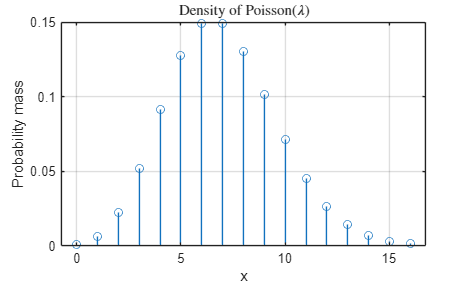

lambda =7;
x = 0:poissinv(0.999,lambda);
poissonDensity = poisspdf(x, lambda);
poissonDistribution = poisscdf(x, lambda);

% Plot the Poisson density function
stem(x, poissonDensity)
title('Density of Poisson($\lambda$)', 'Interpreter','latex')
xlabel('x')
ylabel('Probability mass')
grid on;

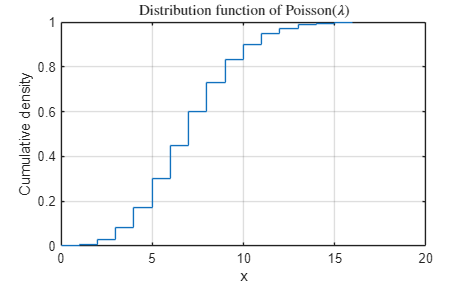


% Plot the Poisson distribution function
stairs(x, poissonDistribution)
title('Distribution function of Poisson($\lambda$)', 'Interpreter','latex')
xlabel('x')
ylabel('Cumulative density')
grid on;

The Poisson distribution has discrete support, so computation will be similar to Question 1. 

poisscdf(3, lambda)

ans = 0.0818

poisscdf(2, lambda)

ans = 0.0296

sum(poisspdf([19, 20], lambda))

ans = 1.1536e-04

1 - poisscdf(0, lambda)

ans = 0.9991

Suppose that astronomers find on average *one star per 16* $\textit{ly}^{3}$—this is the mean rate of occurrence. Let $X$ denote the number of stars we find in a random 16 cubic light year area. We may consider $X\sim\text{Pois}(\lambda = 1)$ since the region we are observing is bounded. The probability of finding at least two stars in a 16$\textit{ly}^{3}$ region is


$$\mathbb{P}\{X\geq 2\} = 1 - \mathbb{P}\{X < 2\} = 1 - \mathbb{P}\{X\leq 1\} = 1 - F(1\vert \lambda = 1).$$


1 - poisscdf(1, 1)

ans = 0.2642

We wish to determine the volume of space which we should observe so that the probability of observing at least one star is 95%. Let $n$ denote the number of 16$\textit{ly}^{3}$ blocks that we observe. We wish to solve the statement


$$\mathbb{P}(nX \geq 1) > 0.95$$


for $n$. Note that $nX =: X_{n}\sim Poiss(n\lambda)$ since we treat the presence of stars in any region to be independent. Thus,

$\mathbb{P}(X_{n}\geq 1) = 1 - \mathbb{P}(X_{n} = 0) = 1 - \mathrm{e}^{n\lambda}$.

Rearranging and solving for $n$ yields the inequality $n > -\log(0.05) / \lambda$. Hence, we should view at least $-16\times\log(0.05) \approx 47.93$ cubic light years of space so that we can see at least one star with 95% probability. 

-log(0.05) % how many 16 ly^3 blocks should we observe

ans = 2.9957

-16 * log(0.05) % convert this to actual volume of space

ans = 47.9317

*How would this answer change if we wanted to know the number of intersections to observe to record at least one car crash with probability 0.95?*

## Question 3

Let $X\sim U(a,b)$, where $a$ and $b$ are the bounds of $X$, with $a\leq b$. The Uniform distribution is continuous and, for $a < x < b$, has density $f(x) = (b - a)^{-1}$ and distribution $F(x) = (x - a) / (b - a)$.  Continuity of the density implies that $X$ taking any discrete set of values has probability 0. For example, let $A,B\subset (a,b)$, where $A$ and $B$ are respectively finite and countable. Then $\mathbb{P}\{X\in A\} = \mathbb{P}\{X\in B\} = 0$. In particular, for $a < x < b$, 


$$F(x) = \mathbb{P}\{X \leq x\} = \mathbb{P}\{X < x\} \cup\{X = x\} = \mathbb{P}\{X < x\} + \mathbb{P}\{X = x\} = \mathbb{P}\{X < x\}.$$


Hence, for$X\sim U[-1,1]$, we have $\mathbb{P}\{X < 0\} = \mathbb{P}\{X \leq 0\} = F(0)$ and 

$\mathbb{P}\{-0.9\leq X\leq 0.8\} = \mathbb{P}\{X \leq 0.8\} - \mathbb{P}\{X<-0.9\} = \mathbb{P}\{X \leq 0.8\} - \mathbb{P}\{X\leq-0.9\} = F(0.8) - F(-0.9)$.

range =[-1 1]

range =     -1     1


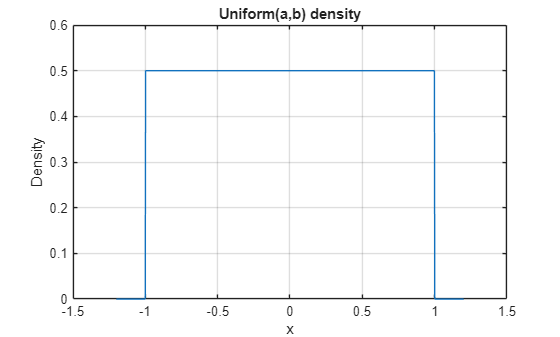

a = range(1);
b = range(2);

x = linspace(a - 0.2, b + 0.2, 1000);
uniformDensity = unifpdf(x, a, b);
uniformDistribution = unifcdf(x, a, b);

plot(x, uniformDensity);
ylim([0, max(uniformDensity) * 1.2]); % extend the y-limits so that the density doesn't coincide with the ceiling
xlabel('x'); 
ylabel('Density');
title('Uniform(a,b) density');
grid on;

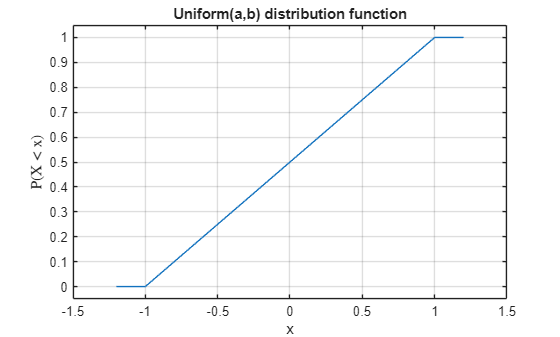


plot(x, uniformDistribution);
xlabel('x'); 
ylabel('P(X < x)', 'Interpreter','latex');
title('Uniform(a,b) distribution function');
ylim([-0.05 1.05]);
grid on;

% set a = -1 and b = 1
% matlab default arguments are a = 0 and b = 1
unifcdf(0, a, b)

ans = 0.5000

unifcdf(0.8, a, b) - unifcdf(-0.9, a, b)

ans = 0.8500

We now want to determine where the 90% of the $U[-1,1]$ distribution is located—determine $x_{*}$ such that $\mathbb{P}\{-x_{*} \leq X \leq x_{*}\} = 0.9$. By symmetry $\mathbb{P}\{-x_{*} \leq X \leq x_{*}\} = 2\mathbb{P}\{X \leq x_{*}\} - 1$, which implies that $x_{*}$ satisfies $\mathbb{P}\{X\leq x_{*}\} = 0.95$. Finding $x_{*}$ is the reverse opposite (*or inverse*) computation for the distribution function—also known as finding the quantiles. Symbolically, if $F^{-1}$ is the quantile function, then $x_{*} = F^{-1}(0.95)$. We can use `unifinv()` to find the necessary quantiles here.

unifinv(0.95, a, b)

ans = 0.9000

To answer part (b), set $a = 0.2050$ and $b = 0.2150$. Note that 0.2125 is the midpoint of $(a,b)$, so $\mathbb{P}\{X > 0.2125\} = \mathbb{P}\{X \leq 0.2125\} = 0.5$. 

unifinv(1 - 0.1, 0.2050, 0.2150)

ans = 0.2140

## Question 4

Recall—from last week—that the Exponential distribution can be used to measure the survival time of objects, where the positive parameter $\mu$ identifies the mean of the distribution. The Exponential distribution has support on $[0,\infty)$, with continuous density $f(x) = \mu^{-1}\exp\left(-x\mu^{-1}\right)$ and distribution function $F(x) = 1 - \exp\left(-x\mu^{-1}\right)$. *Note that we had previously defined the Exponential distribution with respect to a 'rate parameter', whereas here we have defined it with respect to scale parameter. *

mu = 2;

% continuity implies $Pr(W <= 2) = Pr(W < 2)
expcdf(2, mu)

ans = 0.6321


% Pr(10 < W < 13) = Pr(W < 13) - Pr(W < 10)
expcdf(13, mu) - expcdf(10, mu)

ans = 0.0052


% Exponential distributions have positive support, so Pr(W > t) = 1 for all
% non-positive t
1 - expcdf(-5, mu)

ans = 1

expcdf(-5, mu, 'upper') % alternative formulation using 'upper'

ans = 1

expcdf(-0.00000001, mu, 'upper') % try for any nonpositive numbers

ans = 1

expcdf(0, mu, 'upper')

ans = 1

## Question 6

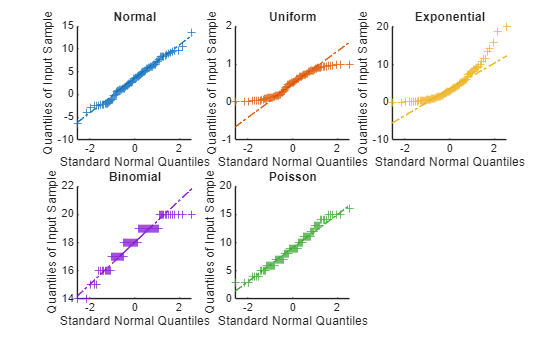

n = 100;
% generate n-by-1 array
% MATLAB will generate an n-by-n array by default
normal = normrnd(3, 4, n, 1);
uniform = unifrnd(0, 1, n, 1);
exponential = exprnd(4, n, 1);
binomial = binornd(20, 0.9, n, 1);
poisson = poissrnd(9, n, 1);

% Plug data into a single cell array
dataVectors = {normal, uniform, exponential, binomial, poisson};
names = {'Normal', 'Uniform', 'Exponential', 'Binomial', 'Poisson'};
colors = lines(length(names));

figure
for i = 1:5
    subplot(2, 3, i)
    h = qqplot(dataVectors{i});
    h(1).MarkerEdgeColor = colors(i,:);
    h(1).MarkerFaceColor = colors(i,:);
    h(2).Color = colors(i,:);
    h(3).Color = colors(i,:);
    title(names{i})
end

Let's take a look at a quantile plot for real data. Recall the `inflows` data set, where we observed that the values were significantly right-skewed. 

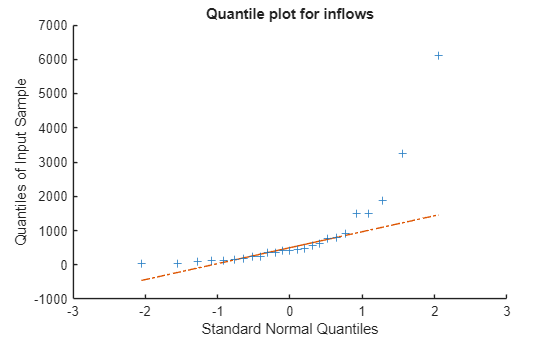

[~, inflow] = readvars("data\inflows.txt");

figure
qqplot(inflow)
title("Quantile plot for inflows")

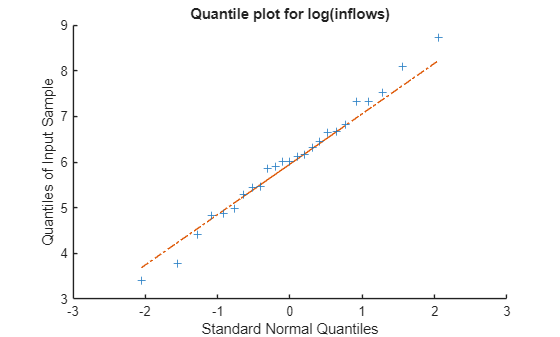


qqplot(log(inflow))
title("Quantile plot for log(inflows)")